Aufgabe 1)

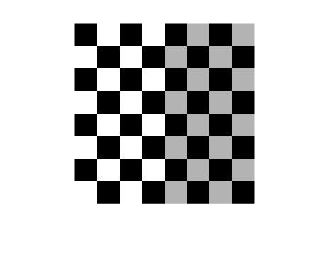

% a)
% Die weißen felder der rechten Seite sind deutlich dunkler / grau.
img = imread("schach.jpg");
figure;
imshow(img);

% b)
figure;
harris = detectHarrisFeatures(img);
harris 

harris =   49×1 cornerPoints array with properties:

    Location: [49×2 single]
      Metric: [49×1 single]
       Count: 49


c) 49 Keypoints wurden gefunden

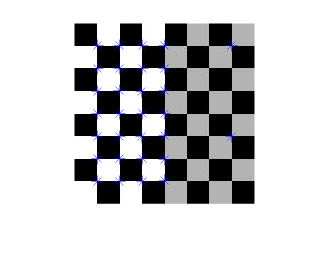

% d)
imshow(img);hold on;
strongest_h = harris.selectStrongest(30);
plot(strongest_h.Location(:,1), strongest_h.Location(:,2), 'b*', MarkerSize=10);

e) Die Keypoints befinden sich an den ecken der Felder => der Harris-Detector ist ein Eckpunkt-Detektor

% f)
shi = detectMinEigenFeatures(img);
shi

shi =   49×1 cornerPoints array with properties:

    Location: [49×2 single]
      Metric: [49×1 single]
       Count: 49


sprintf("There ahve been found %d feautures", shi.Count)

ans = "There ahve been found 49 feautures"

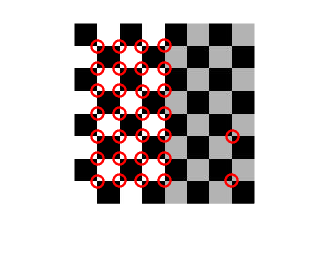

figure;
imshow(img);hold on;
strongest_s = shi.selectStrongest(30);
plot(strongest_s.Location(:,1), strongest_s.Location(:,2), 'ro', MarkerSize=10, LineWidth=2);

Die beider Detektoren haben, auf der 'dunklen Seite', nicht die gleichen Keypoints gefunden.

% g)
surf = detectSURFFeatures(img);
surf

surf =   272×1 SURFPoints array with properties:

              Scale: [272×1 single]
    SignOfLaplacian: [272×1 int8]
        Orientation: [272×1 single]
           Location: [272×2 single]
             Metric: [272×1 single]
              Count: 272


sprintf("There ahve been found %d feautures", surf.Count)

ans = "There ahve been found 272 feautures"

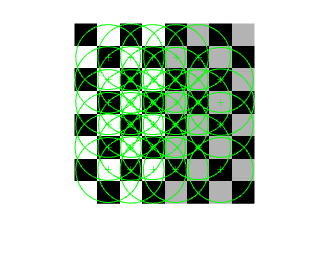

figure;
imshow(img);hold on;
strongest_surf = surf.selectStrongest(30);
strongest_surf.plot

Die Kreise geben die Skalen der Keypoints an. Je größer der Kreis je größer die Skala auf der der Keypoint erkannt wurde.

SURF ist im gegensatz zu Shi oder Harris kein Ecken-Detektor sondern ein Blob-Detektor.